## Load data

warning off;
addpath('./hyper_params');
prefix = 'us'; % Can be changed to 'global'
eval(['load_data_' prefix]);

## Data smoothing

un = 20;
dalpha = 1;
T_full = 171;
T_full = size(data_4, 2);
smooth_factor = 7;
data_4_s = [data_4(:, 1) cumsum(movmean(diff(data_4')', smooth_factor, 2), 2)];
deaths_s = [deaths(:, 1) cumsum(movmean(diff(deaths')', smooth_factor, 2), 2)];

## Load/Compute Hyperparameters

hyper_day_string = 'latest'; % 'latest' or 'ref_<number>'
try
    clear best_param_list
    eval(['load '  prefix '_hyperparam_' hyper_day_string]);
    if ~exist('best_param_list')
        best_param_list = best_param_list_no;
        MAPEtable_s = MAPEtable_notravel_fixed_s;
    end
catch
    disp('Hyperparams not found. Recalculating')
    [best_param_list, MAPEtable_s] = hyperparam_tuning(data_4, data_4_s, popu, 0, un, T_full);
    [best_death_hyperparam, one_hyperparam] = death_hyperparams(deaths, data_4_s, deaths_s, T_full, 7, popu, 0, best_param_list, un);
end

dk = best_death_hyperparam(:, 1);
djp = best_death_hyperparam(:, 2);
dwin = best_death_hyperparam(:, 3);

## Load hyperparameters for reference day (social distancing)

% reference_day = 64;
% eval(['load '  prefix '_hyperparam_ref_' num2str(reference_day)]);

start_day = 53; skip_length = 7;
[beta_best, beta_worst, param_best, param_worst, Rt_mat] = best_and_worst((start_day:skip_length:(size(data_4, 2))), 'us');

## Perform death predictions and write files for various factors of unreported cases


un_array = [1 10 20 40]; % Select the ratio of total to reported cases
horizon = 100; % days of reported cases predcitions
dhorizon = horizon; % days of deaths predcitions
compute_region = (popu> 0 & data_4(:, end) > 0); % Compute only for these regions
%compute_region([51, 52, 53, 55, 56]) = 0; 
passengerFlow = 0;
reference_day = 64;
base_infec = data_4(:, T_full);
for un_id = 1:length(un_array)
    % Train with hyperparams before and after
    un = un_array(un_id); % Select the ratio of true cases to reported cases. 1 for default.
    
    beta_after = var_ind_beta_un(data_4_s(:, 1:T_full), passengerFlow*0, best_param_list(:, 3)*0.1, best_param_list(:, 1), un, popu, best_param_list(:, 2), 0, compute_region);
    
    disp('trained reported cases');
    
    % Predict with unreported cases
    
    infec_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_after, popu, best_param_list(:, 1), horizon, best_param_list(:, 2), un, base_infec);
    infec_released_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_worst, popu, param_worst(:, 1), horizon, param_worst(:, 2), un, base_infec);
    infec_restricted_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_best, popu, param_best(:, 1), horizon, param_best(:, 2), un, base_infec);
    
    disp('predicted reported cases');
    
    infec_un_re = infec_un - repmat(base_infec - data_4_s(:, T_full), [1, size(infec_un, 2)]);
    infec_data = [data_4_s(:, 1:T_full), infec_un_re];
    infec_data_released = [data_4_s(:, 1:T_full), infec_released_un];
    infec_data_restricted = [data_4_s(:, 1:T_full), infec_restricted_un];
    base_deaths = deaths(:, T_full);
    
    [death_rates] = var_ind_deaths(data_4_s, deaths_s, dalpha, dk, djp, dwin, 0, compute_region);
    disp('trained deaths');
    
    [pred_deaths] = var_simulate_deaths(infec_data, death_rates, dk, djp, dhorizon, base_deaths, T_full-1);
    [pred_deaths_released] = var_simulate_deaths(infec_data_released, death_rates, dk, djp, dhorizon, base_deaths, T_full-1);
    [pred_deaths_restricted] = var_simulate_deaths(infec_data_restricted, death_rates, dk, djp, dhorizon, base_deaths, T_full-1);

    disp('predicted deaths');

    T_val = min([14,  size(deaths, 2)-T_full-1]); % For error calculation
    gtruth = diff(deaths(compute_region, T_full+1:T_full+T_val+1)')';
    predvals = diff(pred_deaths(compute_region, 1:T_val+1)')';
    
    [meanMSE, meanMAPE] = calc_errors(gtruth, predvals);
    
    disp(['Unreported factor:: ' num2str(un), ' Errors:: ', num2str([meanMSE meanMAPE]) ]);
   
    eval(['deaths_un_' num2str(un) '= pred_deaths;']);
    eval(['infec_un_' num2str(un) '= infec_un;']);
    eval(['deaths_released_un_' num2str(un) '= pred_deaths_released;']);
    eval(['deaths_restricted_un_' num2str(un) '= pred_deaths_restricted;']);
end

trained reported cases


predicted reported cases


trained deaths


predicted deaths


Unreported factor:: 1 Errors:: NaN    0


trained reported cases


predicted reported cases


trained deaths


predicted deaths


Unreported factor:: 10 Errors:: NaN    0


trained reported cases


predicted reported cases


trained deaths


predicted deaths


Unreported factor:: 20 Errors:: NaN    0


trained reported cases


predicted reported cases


trained deaths


predicted deaths


Unreported factor:: 40 Errors:: NaN    0


## Plot death predictions

figure('DefaultAxesFontSize',18);
sel_reg = "California"; % Select a region to predict
un = 20;
sel_horizon = 45

sel_horizon = 45

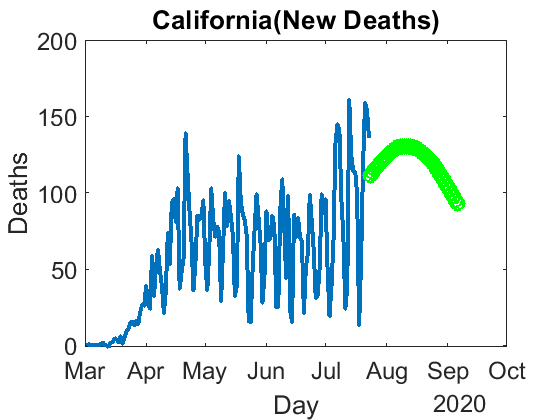

 

xx = find(startsWith(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx(1);
end

eval(['deaths_un = deaths_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['infec_un = infec_un_' num2str(un) '(:, 1:sel_horizon);']);
%eval(['deaths_released_un = deaths_released_un_' num2str(un) '(:, 1:sel_horizon);']);

offset = 40;
trueshow = (offset:size(deaths, 2));
Tx = datetime(2020, 1, 22)+ caldays(trueshow);
plot(Tx(2:end), diff(deaths(cid, trueshow)), 'LineWidth', 3);
hold on;

Tx = datetime(2020, 1, 22)+caldays((T_full+1:T_full+sel_horizon));
yy = [deaths(cid, T_full) deaths_un(cid, :)];
yy = diff(yy); Tx = Tx(1:end);
plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10);
% hold on;
% Tx = datetime(2020, 1, 22)+caldays((T_full:T_full+sel_horizon-1));
% yy = deaths_released_un(cid, :);
% yy = diff(yy); Tx = Tx(2:end);
% plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); 
hold off;

title([countries{cid} '(New Deaths)'])
xlabel('Day');
ylabel('Deaths');

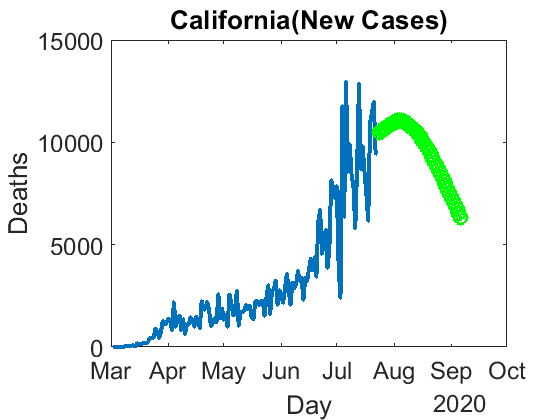


Tx = datetime(2020, 1, 22)+ caldays(trueshow);
plot(Tx(2:end), diff(data_4(cid, trueshow)), 'LineWidth', 3);
hold on;

Tx = datetime(2020, 1, 22)+caldays((T_full+1:T_full+sel_horizon));
yy = [data_4(cid, T_full) infec_un(cid, :)];
yy = diff(yy); Tx = Tx(1:end);
plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10);
% hold on;
% Tx = datetime(2020, 1, 22)+caldays((T_full:T_full+sel_horizon-1));
% yy = deaths_released_un(cid, :);
% yy = diff(yy); Tx = Tx(2:end);
% plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); 
hold off;

title([countries{cid} '(New Cases)'])
xlabel('Day');
ylabel('Deaths');

## Scenarios

figure('DefaultAxesFontSize',18);
sel_reg = "California"; % Select a region to predict
un = 20;
sel_horizon = 75

sel_horizon = 75

 

xx = find(startsWith(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx(1);
end

eval(['deaths_un = deaths_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['deaths_released_un = deaths_released_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['deaths_restricted_un = deaths_restricted_un_' num2str(un) '(:, 1:sel_horizon);']);


offset = 60;
trueshow = (offset:size(deaths, 2));
Tx = datetime(2020, 1, 22)+ caldays(trueshow);
yy = diff(deaths(cid, trueshow));
yy = deaths(cid, trueshow);
plot(Tx(1:end), yy, 'LineWidth', 3);
hold on;

Tx = datetime(2020, 1, 22)+caldays((T_full+1:T_full+sel_horizon));
yy = [deaths(cid, T_full) deaths_un(cid, :)];
yy = diff(yy);
yy = deaths_un(cid, :);
plot(Tx, yy, 'b', 'Marker', 'x', 'LineWidth', 2, 'MarkerSize', 10);
hold on;

yy = [deaths(cid, T_full) deaths_released_un(cid, :)];
yy = diff(yy);
yy = deaths_released_un(cid, :);
plot(Tx, yy, 'r', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); 
hold on;

yy = [deaths(cid, T_full) deaths_restricted_un(cid, :)];
yy = diff(yy);
yy = deaths_restricted_un(cid, :)

yy = 	1.0e+04 *

    0.8449    0.8562    0.8672    0.8778    0.8881    0.8979    0.9073    0.9161    0.9243    0.9320    0.9392    0.9458    0.9519    0.9573    0.9621    0.9663    0.9701    0.9735    0.9766    0.9794    0.9819    0.9841    0.9861    0.9878    0.9894    0.9908    0.9921    0.9932    0.9942    0.9951    0.9959    0.9966    0.9972    0.9978    0.9983    0.9987    0.9991    0.9995    0.9998    1.0001    1.0004    1.0006    1.0008    1.0010    1.0011    1.0013    1.0014    1.0015    1.0016    1.0017


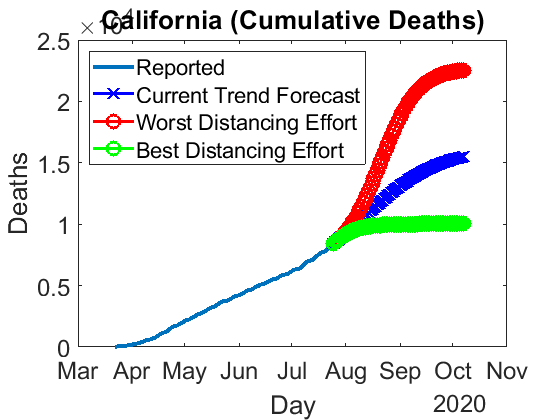

plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); 
hold off;

legend({'Reported'; 'Current Trend Forecast'; 'Worst Distancing Effort'; 'Best Distancing Effort'}, 'location', 'northwest');

title([countries{cid} ' (Cumulative Deaths)'])
xlabel('Day');
ylabel('Deaths');

## Write files

startdate = datetime(2020, 1, 23) + caldays(T_full);
lowidx = popu < 0;
writetable(infec2table(infec_un_20, countries, lowidx, startdate), [prefix '_forecasts_quarantine_' num2str(T_full) '.csv']);
writetable(infec2table(deaths_un_20, countries, lowidx, startdate), [prefix '_deaths_quarantine_' num2str(T_full) '.csv']);

